clear
clc
close all
% Hello, this script calculates a DMA beampattern. 
% Only works for distinct nulls. Q has other equation for null multiplicity

% To-do:
% Calculate WNG
% Overlay multiple frequencies
% Pretty up the plot

% Order of ideal function
N = 3

N = 3


% Number of microphones M > N 
M = N +1

M = 4

 
% Steering of main lobe
steerAng =70.01

steerAng = 70.0100

xs = cosd(steerAng);

% Signal frequency (Hz)
f = 1e3;                        

% Microphone spacing (m)
d = 0.01;                       

% Speed of sound (m/s)
c = 343;                                       

% Temporary null vector dim = N
nullAngles = [flip((steerAng-180/N:-180/N:0)) (steerAng+180/N:180/N:180)]' 

nullAngles =    10.0100
  130.0100


nullAngles = [125 175]'

nullAngles =    125
   175



% Concat with steering angle
x = [xs; cosd(nullAngles)] 

x =     0.3419
   -0.5736
   -0.9962


%x = [xs; sort(cosd(nullAngles))] % SORT???

% Set up linear system of equations
epsi = diag(0:N);
Q = cat(1, [(x(1).^(0:N)); (x(1).^(0:N)*epsi)], x(2:end).^(0:N))

Q =     1.0000    0.3419    0.1169    0.0400
         0    0.3419    0.2337    0.1199
    1.0000   -0.5736    0.3290   -0.1887
    1.0000   -0.9962    0.9924   -0.9886



% Inverse with constraint function
a = Q\eye(length(Q),1)          

a =     0.7599
    1.2294
   -1.0279
   -1.5020


xN = - a(end-1)/a(end) - sum(x(2:end))

xN = 0.8854


% Determined null vector
x = [x; xN]      

x =     0.3419
   -0.5736
   -0.9962
    0.8854


%x = [x(1); sort(x(2:end))]


% Phase vector of microphone array
D = exp((-1i*2*pi*f*d*(0:M-1).*x)/c)

D =    1.0000 + 0.0000i   0.9980 - 0.0626i   0.9922 - 0.1249i   0.9824 - 0.1868i
   1.0000 + 0.0000i   0.9945 + 0.1049i   0.9780 + 0.2086i   0.9507 + 0.3100i
   1.0000 + 0.0000i   0.9834 + 0.1815i   0.9341 + 0.3569i   0.8539 + 0.5205i
   1.0000 + 0.0000i   0.9869 - 0.1615i   0.9478 - 0.3187i   0.8839 - 0.4676i



% Filter weights
if M == N + 1
    h = D\eye(N+1,1) 
else
    %h = D'*(D*D')\eye(N+1,1)
    h = D'*inv(D*D')*eye(N+1,1)
end

h = 1.0e+02 *

   0.3827 - 2.4234i
  -0.8319 + 7.2326i
   0.5335 - 7.2607i
  -0.0767 + 2.4522i



% Generate input
ang_resolution = 360;
thetas = linspace(0, 2*pi,ang_resolution);
freqs = linspace(1e3, 12e3, 10);
%freqs = 1e3;
output = zeros(length(freqs),length(thetas));
for k=1:length(freqs)
     D = exp(-1i*2*pi*freqs(k)*d*(0:M-1).*x/c)
    % Filter weights
    if M == N + 1
        h = D\eye(N+1,1) 
    else
        %h = D'*(D*D')\eye(N+1,1)
        h = D'*inv(D*D')*eye(N+1,1)
    end
    Y = exp(-1i*2*pi*freqs(k)*d*(0:M-1).*cos(thetas(:))/c)'; 

    output(k,:) = h'*Y;
end

D =    1.0000 + 0.0000i   0.9980 - 0.0626i   0.9922 - 0.1249i   0.9824 - 0.1868i
   1.0000 + 0.0000i   0.9945 + 0.1049i   0.9780 + 0.2086i   0.9507 + 0.3100i
   1.0000 + 0.0000i   0.9834 + 0.1815i   0.9341 + 0.3569i   0.8539 + 0.5205i
   1.0000 + 0.0000i   0.9869 - 0.1615i   0.9478 - 0.3187i   0.8839 - 0.4676i


h = 1.0e+02 *

   0.3827 - 2.4234i
  -0.8319 + 7.2326i
   0.5335 - 7.2607i
  -0.0767 + 2.4522i


D =    1.0000 + 0.0000i   0.9903 - 0.1387i   0.9615 - 0.2747i   0.9141 - 0.4055i
   1.0000 + 0.0000i   0.9729 + 0.2314i   0.8929 + 0.4502i   0.7645 + 0.6446i
   1.0000 + 0.0000i   0.9189 + 0.3945i   0.6887 + 0.7250i   0.3469 + 0.9379i
   1.0000 + 0.0000i   0.9357 - 0.3527i   0.7512 - 0.6600i   0.4702 - 0.8826i


h =    7.7489 -21.3584i
 -16.0749 +62.5081i
  10.6503 -63.6572i
  -1.5767 +22.6659i


D =    1.0000 + 0.0000i   0.9768 - 0.2140i   0.9084 - 0.4181i   0.7978 - 0.6029i
   1.0000 + 0.0000i   0.9352 + 0.3541i   0.7493 + 0.6622i   0.4663 + 0.8846i
   1.0000 + 0.0000i   0.8089 + 0.5880i   0.3086 + 0.9512i  -0.3097 + 0.9508i
   1.0000 + 0.0000i   0.8480 - 0.5301i   0.4381 - 0.8989i  -0.1050 - 0.9945i


h =    3.2246 - 5.3862i
  -6.1394 +15.2899i
   4.3196 -15.9002i
  -0.6745 + 6.2414i


D =    1.0000 + 0.0000i   0.9576 - 0.2881i   0.8340 - 0.5518i   0.6397 - 0.7686i
   1.0000 + 0.0000i   0.8822 + 0.4709i   0.5565 + 0.8309i   0.0997 + 0.9950i
   1.0000 + 0.0000i   0.6588 + 0.7523i  -0.1320 + 0.9912i  -0.8327 + 0.5537i
   1.0000 + 0.0000i   0.7270 - 0.6867i   0.0570 - 0.9984i  -0.6441 - 0.7649i


h =    1.7556 - 1.9584i
  -2.9308 + 5.3834i
   2.2631 - 5.6964i
  -0.3822 + 2.6022i


D =    1.0000 + 0.0000i   0.9328 - 0.3605i   0.7401 - 0.6725i   0.4479 - 0.8941i
   1.0000 + 0.0000i   0.8146 + 0.5800i   0.3272 + 0.9450i  -0.2816 + 0.9595i
   1.0000 + 0.0000i   0.4760 + 0.8794i  -0.5468 + 0.8373i  -0.9966 - 0.0822i
   1.0000 + 0.0000i   0.5775 - 0.8164i  -0.3330 - 0.9429i  -0.9621 - 0.2727i


h =    1.1009 - 0.8343i
  -1.5202 + 2.2666i
   1.3455 - 2.3745i
  -0.2528 + 1.3580i


D =    1.0000 + 0.0000i   0.9025 - 0.4307i   0.6289 - 0.7775i   0.2327 - 0.9725i
   1.0000 + 0.0000i   0.7336 + 0.6796i   0.0764 + 0.9971i  -0.6215 + 0.7834i
   1.0000 + 0.0000i   0.2697 + 0.9629i  -0.8545 + 0.5195i  -0.7307 - 0.6827i
   1.0000 + 0.0000i   0.4054 - 0.9141i  -0.6713 - 0.7412i  -0.9497 + 0.3132i


h =    0.7529 - 0.3703i
  -0.7909 + 1.0700i
   0.8566 - 1.0182i
  -0.1849 + 0.8184i


D =    1.0000 + 0.0000i   0.8669 - 0.4985i   0.5030 - 0.8643i   0.0052 - 1.0000i
   1.0000 + 0.0000i   0.6406 + 0.7679i  -0.1794 + 0.9838i  -0.8704 + 0.4924i
   1.0000 + 0.0000i   0.0501 + 0.9987i  -0.9950 + 0.1000i  -0.1497 - 0.9887i
   1.0000 + 0.0000i   0.2174 - 0.9761i  -0.9054 - 0.4245i  -0.6112 + 0.7915i


h =    0.5455 - 0.1484i
  -0.3780 + 0.5661i
   0.5641 - 0.3810i
  -0.1456 + 0.5463i


D =    1.0000 + 0.0000i   0.8262 - 0.5633i   0.3654 - 0.9309i  -0.2225 - 0.9749i
   1.0000 + 0.0000i   0.5369 + 0.8436i  -0.4234 + 0.9059i  -0.9916 + 0.1292i
   1.0000 + 0.0000i  -0.1721 + 0.9851i  -0.9408 - 0.3391i   0.4959 - 0.8684i
   1.0000 + 0.0000i   0.0210 - 0.9998i  -0.9991 - 0.0419i  -0.0628 + 0.9980i


h =    0.4114 - 0.0306i
  -0.1334 + 0.3528i
   0.3737 - 0.0515i
  -0.1214 + 0.3943i


D =    1.0000 + 0.0000i   0.7808 - 0.6248i   0.2191 - 0.9757i  -0.4386 - 0.8987i
   1.0000 + 0.0000i   0.4245 + 0.9054i  -0.6396 + 0.7687i  -0.9675 - 0.2529i
   1.0000 + 0.0000i  -0.3857 + 0.9226i  -0.7024 - 0.7118i   0.9276 - 0.3735i
   1.0000 + 0.0000i  -0.1764 - 0.9843i  -0.9378 + 0.3472i   0.5071 + 0.8619i


h =    0.3190 + 0.0376i
   0.0122 + 0.2743i
   0.2412 + 0.1313i
  -0.1062 + 0.3032i


D =    1.0000 + 0.0000i   0.7307 - 0.6827i   0.0678 - 0.9977i  -0.6316 - 0.7753i
   1.0000 + 0.0000i   0.3050 + 0.9523i  -0.8139 + 0.5810i  -0.8016 - 0.5979i
   1.0000 + 0.0000i  -0.5803 + 0.8144i  -0.3266 - 0.9452i   0.9593 + 0.2824i
   1.0000 + 0.0000i  -0.3668 - 0.9303i  -0.7310 + 0.6824i   0.9029 + 0.4298i


h =    0.2519 + 0.0803i
   0.0945 + 0.2622i
   0.1436 + 0.2389i
  -0.0968 + 0.2460i


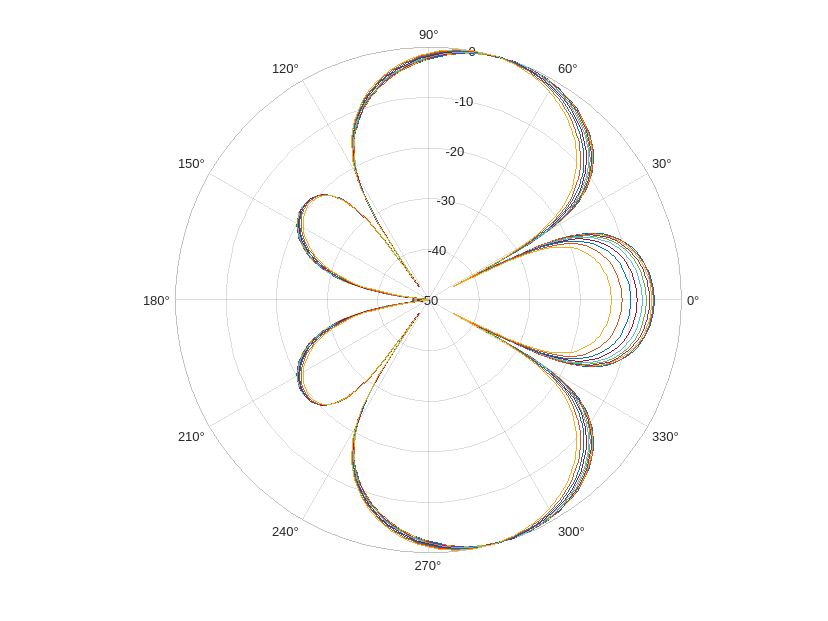



%bp = sqrt(power(real(output),2)+power(imag(output),2));
bp = abs(output);
bp = bp./max(bp')'; % Normalise (gain should already be 1 for designed frequency)
figure()
mindB = -50;
logOutput = mag2db(bp);
%logOutput = 20*log10(bp);
logOutput(logOutput < mindB) = mindB;
polaraxes('RLim', [mindB 0]);
hold on
polarplot(thetas,logOutput)
hold off


%freqs = linspace(1e3, 8e3, 10);
% freqs = 1000;
% output = zeros(length(freqs),length(thetas));
% for k=1:length(freqs)
%      Y = exp(-1i*2*pi*freqs(k)*d*(0:M-1).*cos(thetas(:))/c)'; 
%      % Opdel reel/imagt
%      output(k,:) = h'*Y;
% end

%angp = -180:180;
%output = arrayfactor(d*(0:M-1),angp,h);

% Output of beamformer
%output = h'*Y
%bp = sqrt(power(real(output),2)+power(imag(output),2));
%bp = bp./max(bp')'; % Normalise (gain should already be 1 for designed frequency)
%angp = -180:180;
%figure;
%polarpattern(angp,mag2db(abs(output)),'NormalizeData',true, ...
%    'MagnitudeLimMode','manual','MagnitudeLim',[-50 0])

% N = 4;
% angp = -180:180;
% [w,pos] = diffbfweights(N,0.1,ArrayGeometry='ULA');
% bp = arrayfactor(pos,angp,w);

% [~, maxAng] = max(bp);
% [~, minAng] = min(bp);
% fprintf('Maximum: %d°\n', maxAng*360/angRes)
% fprintf('Minimum: %d°\n', minAng*360/angRes)

% Fs = 44100;
% t = 0:1/Fs:0.01; % Time vector
% signal = sin(2*pi*freqs*t); % Example: Generate a simple sinusoidal signal
% AoI = 44;
% %mic_outputs = zeros(M,length(t));
% for i = 1:M
%     % Calculate time delay for each microphone
%     %time_delay = d*(M+1).*cos(thetas) / c;
%     time_delay = d*(i-1).*cosd(AoI) / c;
%     delay_samples = round(time_delay * Fs);
% 
%     % Apply delay and simulate attenuation
%     delayed_signal = [zeros(1, delay_samples), signal(1:end-delay_samples)];
%     mic_outputs(i, :) = delayed_signal;
% end
% output = h'*mic_outputs;

## 2D plot

%figure()                       % Fo     %Y = exp(-1i*2*pi*freqs(k)*d*(0:M-1).*cos(thetas(:))/c)'; r export
 %polarpattern(thetas*180/pi,20*log10(bp(1,:))', 'AngleResolution', 45, 'LineWidth', ...
 %   3, 'MagnitudeLim', [-50 0], 'ColorOrderIndex', 2)
% figure()
% mindB = -70;
% logOutput = 20*log10(bp);
% logOutput(logOutput < mindB) = mindB;
% polaraxes('RLim', [mindB 0]);
% hold on;
% polarplot(thetas,logOutput)


## Call plot-function

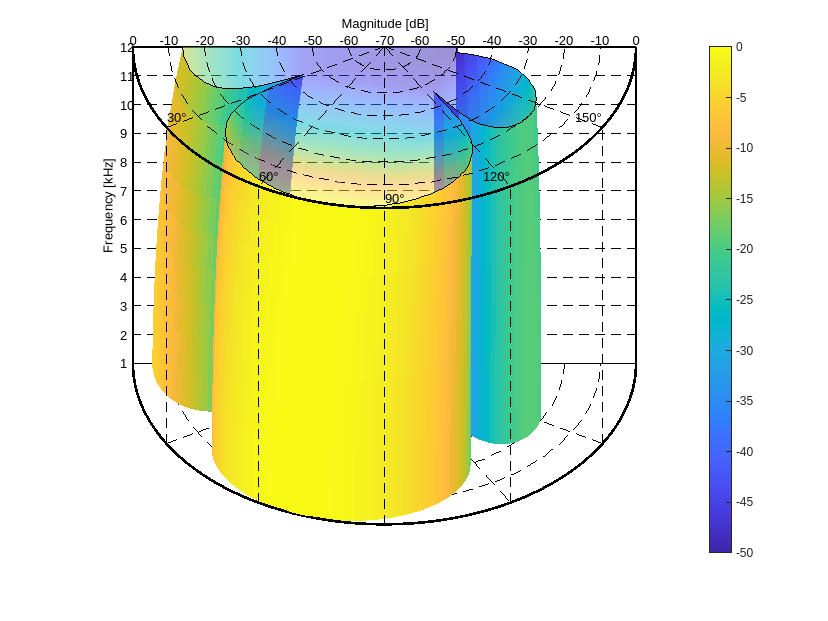

%logOutput = 20*log10(bp);
cylindricalPlot(freqs, thetas, logOutput)

## PLOT ??

% Actual plotting
% [THETA, F] = meshgrid(thetas, freqs);
% 
% logOutput = 20*log10(bp);
% 
% [Y,X] = pol2cart(thetas,logOutput);
% Z = F;
% % X POSITIV
% surf(X, Y, Z/1000, logOutput, 'EdgeColor', 'none');  % Color by the dB value
% xlabel('X (dB)')
% %xlim([0 inf])
% ylabel('Y (dB)')
% zlabel('Frequency (kHz)')
% colorbar  % Add a colorbar to represent the amplitude scale
% title('3D Polar Plot of Radiation Pattern')

% View adjustment to resemble the provided example plot
%view(0, 90, 30)  % Look directly down onto the x-y plane

% Optional: Set the colormap if you want a specific color scheme
%colormap jet;

## PLOT

% logOutput = 20*log10(bp)
% figure()
% for q = 1:length(freqs)
%     [ang, rad] = pol2cart(thetas,logOutput(q,:));
%     if q < length(freqs)
%         %plot3(thetas,logOutput(q,:), (freqs(q):freqs(q+1):length(thetas)))
%         %plot3(thetas,logOutput(q,:), linspace(freqs(q),freqs(q+1),length(thetas)))
%         plot3(ang,rad, linspace(freqs(q),freqs(q),length(thetas))) %q+1
%         hold on
%     else
%        plot3(ang,rad, linspace(freqs(q),freqs(q),length(thetas))) 
%     end
% end
% hold off

## Plotting

% % figure()                       % For export
% % polarpattern(thetas*180/pi,20*log10(bp)', 'AngleResolution', 45, 'LineWidth', ...
% %     3, 'MagnitudeLim', [-50 0], 'ColorOrderIndex', 2)
% % figure()
% mindB = -70;
% logOutput = 20*log10(bp);
% logOutput(logOutput < mindB) = mindB;
% %polaraxes('RLim', [mindB 0]);
% %hold on;
% %polarplot(thetas(1:end/2),logOutput(1:end/2)')
% z_interpolated = linspace(0, 1, length(thetas));
% [ja, nej] = pol2cart(thetas,logOutput(1));
% figure()
% plot3(ja, nej,ones(length(thetas)))
% hold on;
% plot3(ja, nej,zeros(length(thetas)))
% plot3([ja; ja], [nej; nej], [z_interpolated; z_interpolated], 'k--');
% xlabel('X');
% ylabel('Y');
% zlabel('Z');
% title('Combined 3D Polar Plots');
% view(3); % Set the view to 3D
% legend('Polar Plot 1', 'Polar Plot 2');
% hold off;
% 
% %polarscatter(20*log10(bp)')
% 
% %fprintf('Zeros: %i°\n', acosd(x(2:end-1)))
% 